# MSessionExplorer.AlignTime

Ignore code in this section

if exist('isRun', 'var') && isRun
    se = seRaw.Duplicate;
    se.isVerbose = false;
    se.SetColumn('hsv', 'is_tongue_out', @(x) x*0.6, 'each')
else
    edit MSessionExplorer.Examples.AlignTime
    return;
end

**Description**

help MSessionExplorer.AlignTime

  Align epochs by changing the origin of time in each epoch to the specified event times
  
    AlignTime(et)
    AlignTime(et, sourceTbName)
 
  Inputs
    et              An event name in an eventTimes table or a numeric vector of times to align 
                    to. Each time in the vector is relative wrt each row (epoch), which becomes 
                    the new zero time after alignment. 
    sourceTbName    If et is a string, then you must specify the name of an eventTimes table 
                    where this event name should be found. This avoids ambiguity of the same 
                    variable name found in multiple tables. The default is empty. 



**Example 1**

**Align data to new event times**

First, let's see some original data. The plotted are 5 epochs. Dots are 'lickOn' events in 'behavTime' table. Lines are 'is_tongue_out' time series in 'hsv' table. Currently, all epoch time is aligned to cue onset (shown in the 'cue' column of 'behavTime' table). 

se.Preview('behavTime', 'hsv')

    cue      posIndex      water    opto       lickOn           lickOff   
    ___    ____________    _____    ____    _____________    _____________

     0     [6×1 double]    1.832    NaN     [20×1 double]    [20×1 double]
     0     [6×1 double]    1.788    NaN     [19×1 double]    [19×1 double]
     0     [6×1 double]     1.87    NaN     [21×1 double]    [21×1 double]
     0     [6×1 double]    1.755    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.891    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.742    NaN     [14×1 double]    [14×1 double]

         time           is_tongue_out     prob_tongue_out    tongue_bottom_lm
    _______________    

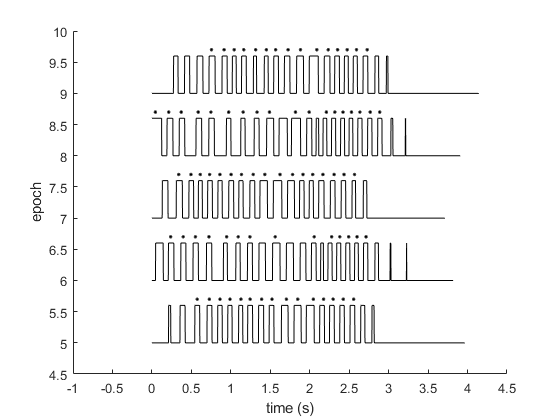


Visualize(se);

Now, we want to align epoch times to the first lickOn in each epoch. First, we need to find them. 

bt = se.GetTable('behavTime');
firstLickOn = NaN(se.numEpochs, 1);
for k = 1 : se.numEpochs
    firstLickOn(k) = bt.lickOn{k}(1);
end
firstLickOn'

ans =     0.3980    0.2750    0.5860    0.2200    0.5740    0.2380    0.3400    0.0440    0.7550    0.1870    0.3600    0.2410    0.7430    0.2360    0.3910    0.2240    0.4880    0.1640    0.5590    0.0620    0.5330    0.2240    5.7410    0.2550    0.3140    0.1920    0.6580    0.1880    0.3540    0.1670    0.5100    0.0880    0.4280    0.2500    0.3980    0.2070    0.3130    0.2610    0.4360    0.2010    0.4930    0.2160    0.3890    0.2440    0.7850    0.2170    0.3760    0.2450    0.4330    0.2270


This single line of code aligns each epoch across all eventTimes and timeSeries tables to firstLickOn

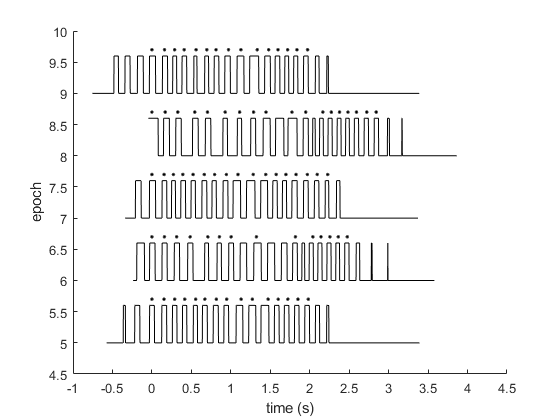

se.AlignTime(firstLickOn);

Visualize(se);

We can align time back to cue (or anything else). This time, however, we use column name and the source table name. 

AlignTime method gurantees the internal consistency and integrity. Any operation can be reversible. 

se.AlignTime('cue', 'behavTime')

Visualize(se);

**Helper function**

function Visualize(se)
[bt, hsv] = se.GetTable('behavTime', 'hsv');
figure; clf
MPlot.PlotRaster(bt.lickOn(5:9), (5:9)+.7, 'Color', 'k');
MPlot.PlotTraceLadder(hsv.time(5:9), hsv.is_tongue_out(5:9), 5:9, 'Color', 'k');
xlim([-1 4.5]); ylim([4.5 10]); xlabel('time (s)'); ylabel('epoch'); box off
end